## Linear Regression - Kepler's 3rd Law (Exoplanets)

In this assignment we apply the basics of linear regression. We will take the semi-major axis and period information for extrasolar planets orbiting other stars to derive Kepler's 3rd Law:


$${\rm Period}^2 = {\rm Semi-major \ axis}^3$$


or


$$P^2 =a^3$$


First load in a dataset.

df = readtable('PHYS410_Exoplanets.csv');
pl_name = transpose(df.pl_name);
period_yr = transpose(df.pl_orbper_yr);
semi_major_AU = transpose(df.pl_orbsmax_n); %taking the semi-majoraxis with noise
stellar_mass = transpose(df.st_mass);

Take the logarithm of both variables.

log_period_yr = log10(period_yr);
log_semi_major_AU = log10(semi_major_AU);
log_stellar_mass = log10(stellar_mass);

Do linear regression using 'polyfit'.

p = polyfit(log_semi_major_AU,log_period_yr,1);
disp("m_best="+string(p(1))+" and b_best="+string(p(2)))

m_best=1.3142 and b_best=-0.22245


Create a line.

max_log_semi_major_AU = max(log_semi_major_AU);
min_log_semi_major_AU = min(log_semi_major_AU);

dummy_log_semi_major_AU = linspace(min_log_semi_major_AU,max_log_semi_major_AU,100);
pred_log_period_yr = p(2)+p(1)*dummy_log_semi_major_AU;

Graph the fit line over the data.

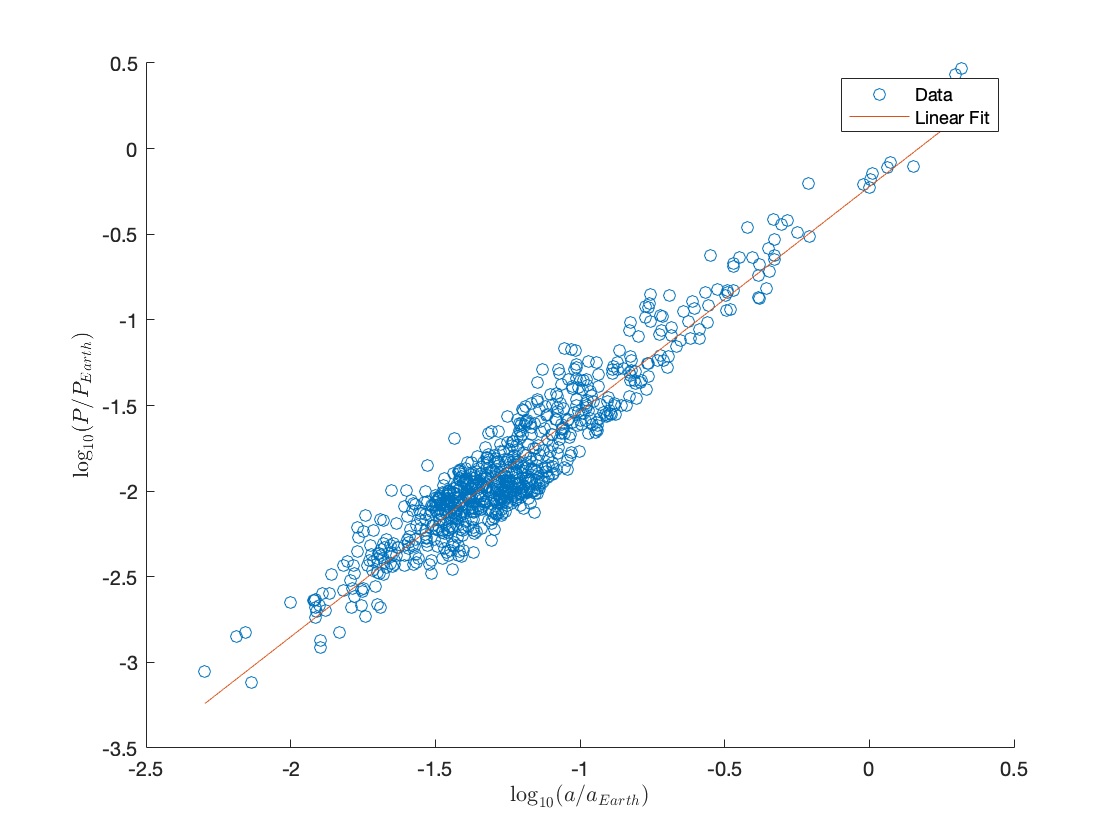

scatter(log_semi_major_AU,log_period_yr)
xlabel("$\log_{10} (a / a_{Earth}) $",'Interpreter','latex')
ylabel("$\log_{10} (P / P_{Earth}) $",'Interpreter','latex')

hold on

plot(dummy_log_semi_major_AU,pred_log_period_yr)
hold off

legend("Data","Linear Fit")

## This isn't quite right is it?

Newton's version of Kepler's 3rd Law depends on the mass of the star (or central object) as well. Assuming the mass of the planet is small compared to the mass of the star, $M_{\rm star} > > M_{\rm planet}$.

$P^2 = \frac{4 \pi^2}{G M_{\rm star}} a^3$.

We can divide by the parameters for Earth to get rid of some of the constants


$$\left( \frac{P}{P_{\rm Earth}} \right)^2 = \frac{M_{\rm \odot}}{M_{\rm star}} \left( \frac{a}{a_{\rm Earth}} \right)^3$$


move the powers around...


$$\frac{P}{P_{\rm Earth}}  = \left( \frac{M_{\rm \odot}}{M_{\rm star}} \right)^{1/2} \left( \frac{a}{a_{\rm Earth}} \right)^{3/2}$$


and take the log...


$$\log_{10} \left( \frac{P}{P_{\rm Earth}} \right) = (-1/2) \log_{10 }\left( \frac{M_{\rm star}}{M_{\rm \odot}} \right)+ (3/2) \log_{10} \left( \frac{a}{a_{\rm Earth}} \right)$$


which is of the form:


$$Y = m_X  X + m_Z Z + B$$


## Multiple Linear Regression

MATLAB *does* have a multiple linear regression code, however it requires a package that we do not currently have access to. So let's try to code this ourselves!

n_rand = 100; % number of random points to consider
mX_rand = 6*rand(n_rand)-3; % rand(n) gives n random numbers uniformly distributed between 0,1
mY_rand = 3*rand(n_rand)-1.5; 
b_rand = rand(n_rand) - 0.5; % gives random number between -0.5 and 0.5

mX_best = 0;
mY_best = 0;
b_best = 0;
resid = 10000;
for i=1:n_rand
    for j=1:n_rand
        for k=1:n_rand
            y_test = mX_rand(i)*log_stellar_mass + mY_rand(j)*log_semi_major_AU + b_rand(k);
            resid_test = sum((y_test - log_period_yr).^2);
            if resid_test < resid
                resid = resid_test;
                mX_best = mX_rand(i);
                mY_best = mY_rand(j);
                b_best = b_rand(k);
                disp("New min residual ="+string(resid))
        
            end
        end
    end
end

New min residual =1139.1974
New min residual =144.9099
New min residual =118.0928
New min residual =113.6561
New min residual =85.8267
New min residual =70.437
New min residual =68.1334
New min residual =48.887
New min residual =47.8179
New min residual =47.3581
New min residual =47.3348
New min residual =47.1738
New min residual =20.0791
New min residual =19.9806
New min residual =17.7081
New min residual =16.9126
New min residual =16.8854
New min residual =16.8388
New min residual =16.5659
New min residual =16.5282
New min residual =15.3882
New min residual =15.2109
New min residual =15.1793
New min residual =15.0749
New min residual =15.0634
New min residual =15.0301
New min residual =15.0197



%disp("mX approx " + string(mX_best))
%disp("mY approx " + string(mY_best))
%disp("b approx " + string(b_best))

disp("log P = "+string(mX_best)+"log M + "+string(mY_best)+"log a + "+string(b_best))

log P = -0.4399log M + 1.3939log a + -0.13149
